# Intro to Computational Imaging (ci) Classes

ciCamera is one of a set of classes that allow experimentation with computational imaging more directly than the previous "lower-level" scene, oi, sensor, and ip structs. Along with ciScene, ciCModule, and ciIP, it provides a programmable wrapper that allows users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule).

History: Initial Version: D. Cardinal 12/2020

ieInit();
ourCamera = ciBurstCamera(); % probably will pass init args
% this seems really backwards but the load & import routines
% don't return an object directly, which is kind of what I want
sensor = sensorFromFile('ar0132atSensorRGB');
ourCamera.cmodule = ciCModule('sensor', sensor); % default

Now we'll define our scene

scenePath = 'Cornell_BoxBunnyChart';        
sceneName = 'cornell box bunny chart';
ourScene = ciScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'numRays', 32);

Read 11 materials
Read 3 textures
Reading C4D geometry information.


optionally set camera and object motion here through parameters/methods of ourScene. 

This sets the Stanford bunny in motion with a vertical movement of about 5cm/s (?) and a tiny rotation. The camera is also set in motion

ourScene.objectMotion = {{'Default_B', [0, 15, 0], [1, 1, 1]}};
ourScene.cameraMotion = {{'unused', [0, 0, 0], [5, 5, 5]}};

For the simplest case we ask our camera to take a picture. By deault it uses the 'Auto' intent. Using 'Burst' will capture more frames if the camera type we are using supports it. 'HDR' will also fire a burst, but bracketed.

%finalImage = ourCamera.TakePicture(ourScene, 'HDR', 'numHDRFrames', 3);
finalImage = ourCamera.TakePicture(ourScene, 'Burst', 'numBurstFrames', 3);

Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm -w /Cornell_BoxBunnyChart -v C:/iset/iset3d/local/Cornell_BoxBunnyChart:/Cornell_BoxBunnyChart vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/Cornell_Box_Multiple_Camer

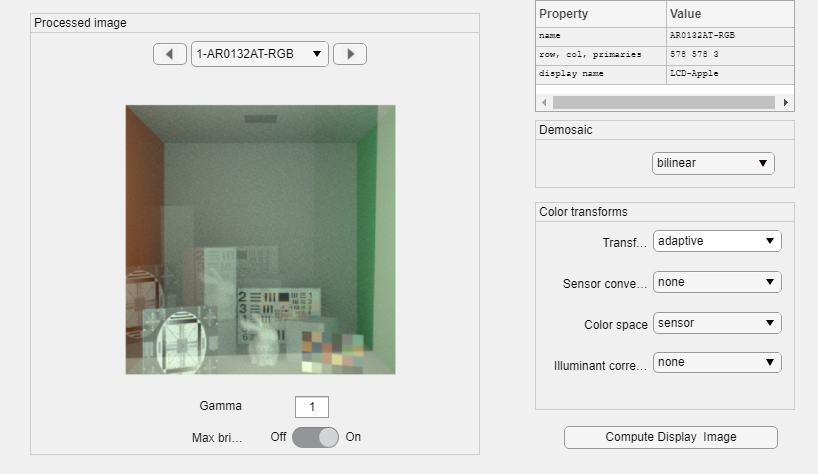

ipWindow(finalImage); % let's see what we got